# **4.2.2 while-end**`语句`

`除了`for-end`语句之外，`MATLAB`还提供了另一种强大的循环语句：`while-end`语句（简称`while`循环）。与`for`循环不同，`**while**`循环的特点在于它允许我们在不知道具体循环次数的情况下执行循环体``，这种灵活性使得`while`循环在某些情境下非常有用，尤其是当我们需要满足某些某些条件时才执行循环操作。`

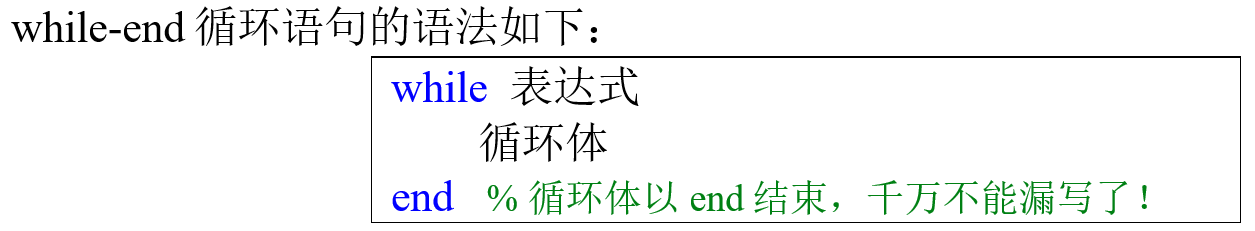

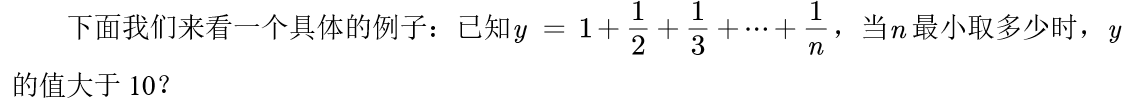

y = 1;  n = 1;
while y <= 10
    n = n + 1;
    y = y + 1/n; 
end
disp(n)
format long g
sum((1./(1:(n-1))))

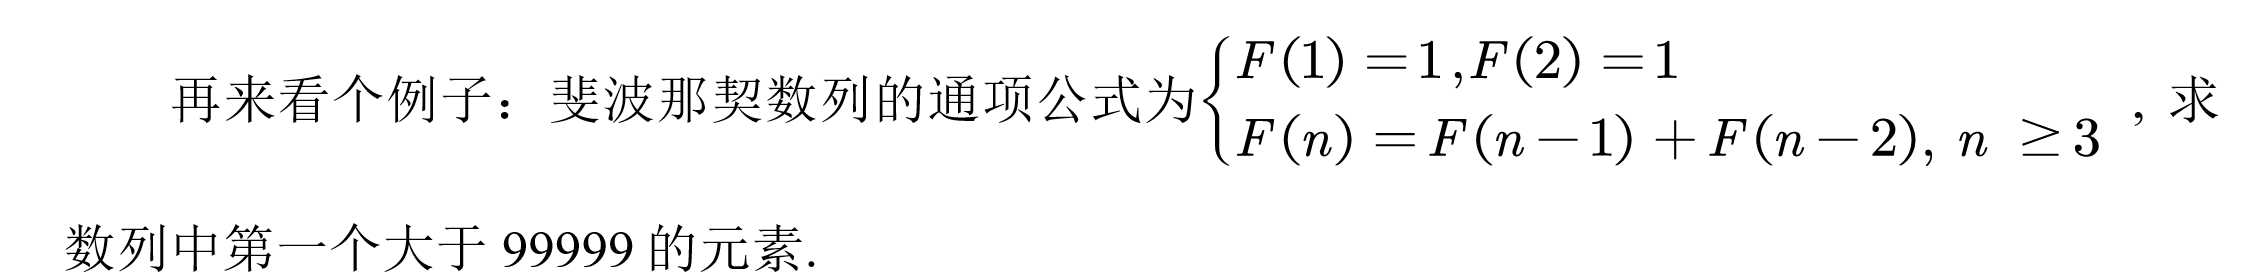

a(1) = 1;
a(2) = 1;
n = 2;
while a(n) <= 99999
    n = n + 1;
    a(n) = a(n-1) + a(n-2);
end
disp(a(end))

      121393


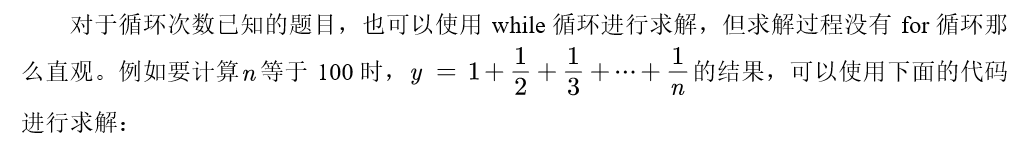

y = 1;  n = 1;
while n < 100
    n = n + 1;
    y = y + 1/n; 
end
disp(y)

    5.1874


`请大家思考：为什么`while`后面的条件表达式是`n < 100`，而不是`n <= 100`？`

如果用for循环就会更加方便：

y = 0;
for n = 1:100
    y = y + 1/n;
end
disp(y)

    5.1874


也可以不用循环：

sum(1./(1:100))

ans = 5.1874

（1）如果不小心执行了一个无限循环（即永远不会自行结束的循环，又称死循环），

可以按下 Ctrl+C 停止执行程序。

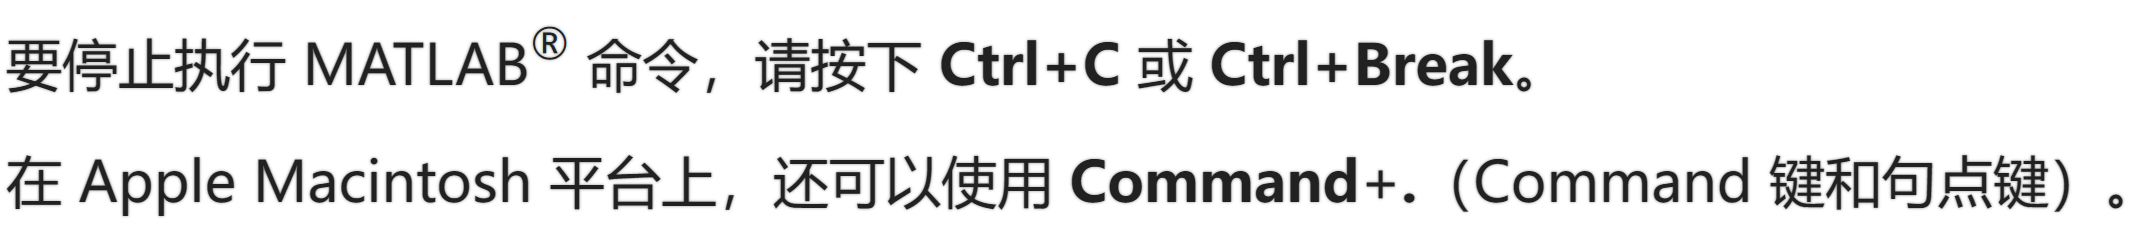

x = 1;
while x < 10
    disp(x)
end

（2）while`后面表达式的计算结果不一定非得是逻辑值`1`或`0`。如果表达式的计算结果是一个数值常数，则只有当这个常数为非零值时循环才会进行；`

ii = 5;
while ii
    disp(ii)
    ii = ii - 1;
end

     5
     4
     3
     2
     1


`若表达式的计算结果是一个数值向量或者矩阵，则仅当该向量或矩阵中的所有元素都是非零数时循环才会进行。`

x = [1 2; 3 4];
while x
    x(1) = 0;
    disp(x)
end

     0     2
     3     4


x = [1 2; 3 0];
while x
    x(1) = 0;
    disp(x)
end

配套的讲解视频可在b站免费观看：

《MATLAB教程新手入门篇（数学建模清风主讲，适合零基础同学观看）》

[https://www.bilibili.com/video/BV1dN4y1Q7Kt/](https://www.bilibili.com/video/BV1dN4y1Q7Kt/)